# AERO40003 Computing and Numerical Methods 1 

# Part 2: Numerical Methods 

# **Coursework 2024**

## Dr. Roderick Lubbock

## Completing this live file

You will submit only this self-contained completed livefile.No other scripts or other files will be marked. When completing this livefile:

- Please make sure all of your code is formatted as code using the "code" button on the Live Editor ribbon;

- Please make sure anything that is not code or code comments is formatted as text;

- Marks for each section and sub-section are shown in bold square brackets;

- Ensure that the entire livefile runs without errors or warnings before submitting! Sections of the file which do not run will not be marked.

#### Code

**EVERY LINE OF CODE (with the exception of plot commands and loop end statements) must have a comment clearly explaining what it does**. Comments should be brief but clear.

All self-contained functions must:

- be entered in the **Functions** section at the bottom of this livefile;

- be named correctly according to the guidance below;

- have a comment on each line of code explaining its function and **how it relates to the equations in the Class Slides or other theory;**

- NOT call built-in MATLAB functions from outside the standard MATLAB toolbox `C:\Program Files\MATLAB\R2022b``\toolbox\matlab` (but you may use these to check your functions).

To check the toolbox of a MATLAB function use the which command. The short name of the toolbox is shown after "**toolbox\**"  For example:

returns `C:\Program Files\MATLAB\R2022b\toolbox\``matlab``\polyfun\spline.m` which means it is in the standard MATLAB toolbox, whereas

returns `C:\Program Files\MATLAB\R2022b\toolbox\``curvefit``\curvefit\fit.m` which means it is in the curvefit toolbox, and not the standard MATLAB toolbox.

#### Plots

You should ensure any plots you are asked to produce have:

- axis labels;

- x and y grid;

- all lines/markers clearly differentiable through use of colour or line/marker type;

- legend (where more than one dataset is plotted), placed so as to minimise overlap with data lines/markes;

- any spaced discrete point data (such as that in the table below) plotted as points (not lines);

- when plotting overlapping functions use solid, dashed, chain-dashed and dotted linetypes to maximise visibility of all lines.

Note that any plots that are not formatted as above (and exemplified in the Computer Labs Code livefiles) **will not be marked.**

#### Numerical outputs

Anywhere you are asked to output values you should:

- Use one of the appropriate built-in MATLAB functions e.g. f`printf;`

- Include a clear description of what the output variable represents;

- Absolute errors should be presented to 3 significant figures.

### Submission

- You should submit your livefile on Blackboard by the deadline stated on Blackboard.

- Please rename the file in the format **NM1_2024_CW_XXXXXX.mlx where XXXXXX is your CID number.**

- As usual, please ensure you receive a confirmation email following submission. Only confirmed submitted files will be marked (partially complete Blackboard submissions will be ignored).

- **Note that submissions may be checked for plagiarism using multiple plagiarism detection softwares, including AI-based software designed specifically to detect the use of ChatGPT, Bard etc., as well as for similarity to other submissions. **

- **If you are trying to decide whether to plagiarise content or submit incomplete content, the choice should always be the latter, because ****a low grade is better than no grade****, and also avoids the stress (for you) and extra work (for departmental staff) involved in plagiarism investigations.**

## Introduction

*Bessel functions* describe electric fields, mechanical vibrations, heat conduction, optical diffraction and other phenomena involving cylindrical or spherical symmetry, for example the displacement of vibrating circular membranes, such as pressure transducer sensing elements and drum skins, as well as temperature distributions in heated cylindrical objects, such as combustor temperature probes and hot dogs in boiling water.  The image below (source:  [https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif](https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif) ) shows an animation of a vibrating drum skin. Everything you could possibly want to know about Bessel functions can be found at the [DLMF: NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/), which is based on a [famous mathemtical handbook](https://www.nist.gov/mathematics-statistics/handbook-mathematical-functions-abramowitz-and-stegun) known as "Abramowitz and Stegun", [available as a pdf here](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf).

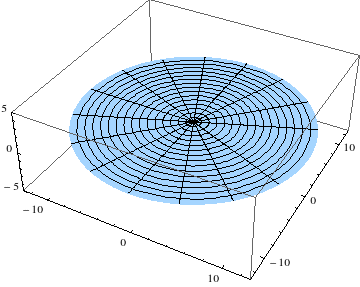

There are various different *kinds* of Bessel functions, including the *first kind *$J_n \left(x\right)$, the *second kind *$Y_n \left(x\right)$ and the *third kind *$H_n \left(x\right)$. For each kind there are also different orders, e.g. integers $n=0,1,2,3\ldotp \ldotp \ldotp$ The Bessel functions of the first kind for the first five integer orders (n = 0 to 4) are plotted below, using the built-in MATLAB function `besselj`. They look a bit like decaying sinusoids, except for some subtle differences as we shall see. 

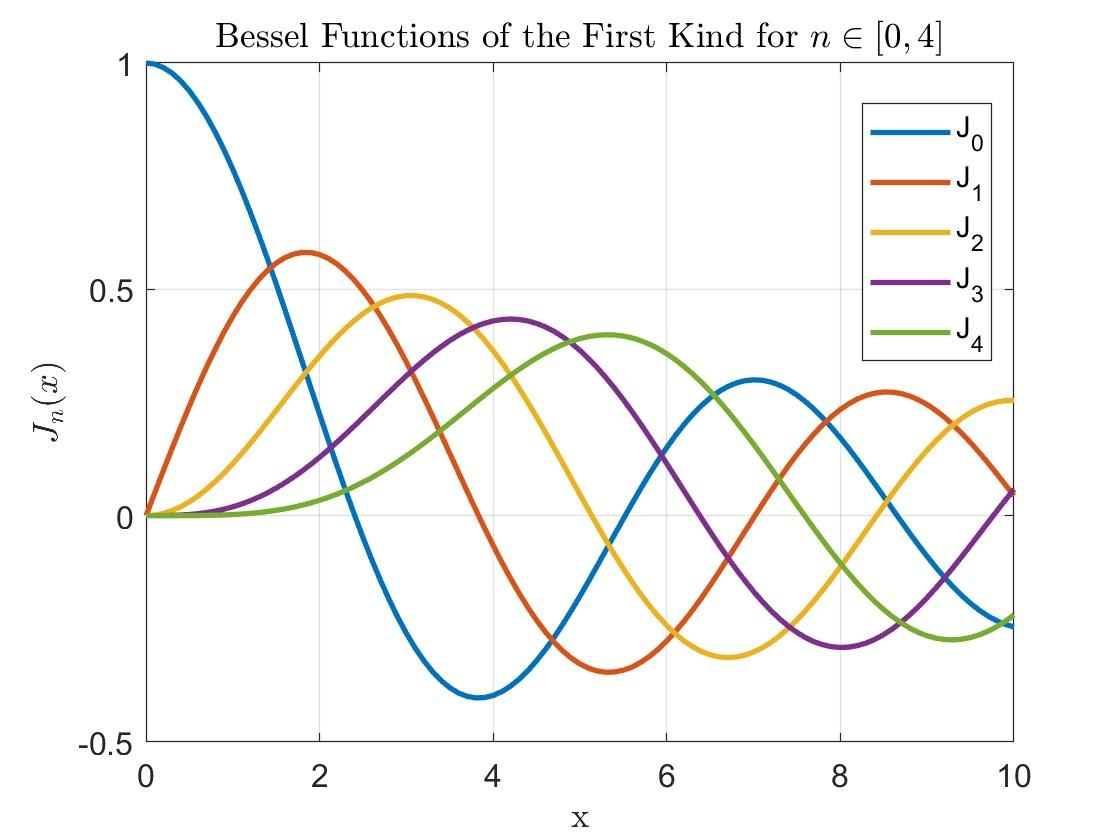

To see how this plot was made run the folllowing code:

Interestingly, the vertical displacement of the drumskin above is given by $u\left(r,\theta \right)=J_3 \left(r\right)\sin \left(3\theta \right)$ in polar coordinates. You should be able to see that, at a certain moment in time (e.g. at the limits of the motion), the vertical displacement plotted in the radial direction resembles $J_3$ in the plot above. You will learn how to obtain the full analytic solution to this sort of time-dependent differential equation later on in the undergraduate course.

**In this coursework you are going to investigate Bessel functions of the first kind, **$J_n \left(x\right)$**, over the interval **$0\le x \le 10$**.**

%INITIALIASE WORKSPACE 
clc
clf
clear all
close all
%set default graph options
set(groot,'defaultLineLineWidth',2)  %sets graph line width as 2
set(groot,'defaultAxesFontSize',12)  %sets graph axes font size as 12
set(groot,'defaulttextfontsize',12)  %sets graph text font size as 12
set(groot,'defaultLineMarkerSize',12)%sets line marker size as 12
set(groot,'defaultAxesXGrid','on')   %sets X axis grid on 
set(groot,'defaultAxesYGrid','on')   %sets Y axis grid on
set(groot, 'DefaultAxesBox', 'on')   %sets Axes boxes on

## Part 1: Interpolation [7 marks]

Bessel functions are usually not amenable to straightforward evaluation (e.g. by hand or with a standard scientific calculator) and are often compiled in standard mathematical tables. One such table is shown below:

`0             0`

`0.5       0.24227`

`  1       0.44005`

`1.5       0.55794`

`  2       0.57672`

`2.5       0.49709`

`  3       0.33906`

`3.5       0.13738`

`  4     -0.066043`

`4.5      -0.23106`

`  5      -0.32758`

`5.5      -0.34144`

`  6      -0.27668`

`6.5      -0.15384`

`  7    -0.0046828`

`7.5       0.13525`

`  8       0.23464`

`8.5       0.27312`

`  9       0.24531`

`9.5       0.16126`

` 10      0.043473`

Investigate the different methods of interpolation covered in the course using the interpolant data in the above table as follows:

- **M1.1:** Write a self-contained MATLAB function **called IntPoly** that fits a polynomial of the maximum possible order to the tabular data using the first approach in Class 4 involving inversion of a matrix of $x$-values. **[0.5]**

- **M1.2:** Write a self-contained MATLAB function **called LagrangePoly** to compute the interpolating Lagrange polynomial that passes through all inerpolant data points. **[0.5]**

- **M1.3:** Write a self-contained MATLAB function **called IntSpline** that performs cubic spline interpolation with natural (free-runout) end conditions. **[0.5]**

- **M1.4: **Using the function from M1.1 interpolate data sampled directly from `besselj `with the same number of points as the original data (i.e. 21), but using Chebyshev spacing. **[0.5]**

All functions should:

- take as input a vector of query points that is evenly spread across the interval and spaced by 0.1

- output the evaluation of the interpolation function at the query points.

- NOT use any MATLAB built-in functions.

Evaluate the performance of your self-contained functions as follows:

- **E1.1:** Plot the interpolated data (as a continuous curve) alongside the tabular data (as points) for all methods on a single plot. **[1]**

- **E1.2:** Evaluate and plot the absolute error in the interpolation compared to `besselj`. Plot the absolute error as a function of $x$ for all methods M1.1 to M1.4 on a single plot. **[1]**

### Questions

- **Q1.1:** How does the performance of the various methods compare in terms of accuracy and computation time? You should compute and output the time required to perform the interpolation along with the $L_2$-norm of the absolute error across the interval using e.g. `sprintf` (as in the Computer Lab Codes) to clearly state which values relate to which method.  **[1]**

- **Q1.2:** Methods 1. and 2. should generate equivalent (i.e. the same) polynomials according to Class 4. Explain with evidence whether or not this is the case.  **[1]**

- **Q1.3:** Compare method 3. with the built-in MATLAB function `spline`. Are the outputs the same? Explain any discrepancies. **[1]**

### Hints

**Method M1.2:** You should use a for loop to step through the product in the basis functions and another for loop to sum the scaled basis fuctions to get the Lagrange polynomial.

### Part 1: Your Solution

clf
data_points = [0, 0;
                   0.5, 0.24227;
                   1, 0.44005;
                   1.5, 0.55794;
                   2, 0.57672;
                   2.5, 0.49709;
                   3, 0.33906;
                   3.5, 0.13738;
                   4, -0.066043;
                   4.5, -0.23106;
                   5, -0.32758;
                   5.5, -0.34144;
                   6, -0.27668;
                   6.5, -0.15384;
                   7, -0.0046828;
                   7.5, 0.13525;
                   8, 0.23464;
                   8.5, 0.27312;
                   9, 0.24531;
                   9.5, 0.16126;
                   10, 0.043473];


y1=IntPoly(data_points);

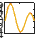

y2=LagrangePoly(data_points);
y3=IntSpline(data_points);
y4=IntPolyChebyshev(data_points);


plot(data_points(:,1),y1(:,1))
hold on 
plot(data_points(:,1),y2(:,1))
plot(data_points(:,1),y3(:,1))

%plot(data_points(:,1),y4(:,1))







Enter explanation here.

## Part 2: Numerical Integration [7 marks]

For integer values of $n$, the bessel function of the first kind may be defined in integral form using *Bessel's integrals* as:


$$J_n(x) = \frac{1}{\pi} \int_0^\pi \cos(n\tau-x\sin\tau)d\tau$$


Investigate the different methods of numerical integration covered in the course to evaluate Bessel's integral for the **first order** Bessel Function of the first kind, $J_1 \left(x\right)$ as follows:

- **M2.1:** Write a self-contained MATLAB function **called trapzJ1** that uses the Trapezium rule. **[0.5]**

- **M2.2:** Write a self-contained MATLAB function** called simpsonJ1** that uses Simpson's 1/3 rule. **[0.5]**

- **M2.3:** Write a self-contained MATLAB function **called gaussJ1** that uses Gauss-Legendre quadrature. **[2]**

All functions should: 

- take as input a vector $x$ that is evenly spread across the interval and spaced by 0.1, as well as the number of points used in the integration, *N*.

- output $J_1 \left(x\right)$. 

You should evaluate the performance of your self-contained functions as follows:

- **E2.1:** Plot the approximated function alongside values computed using `besselj` as a function of $x$ for all methods on a single figure. **[0.5]**

- **E2.2:** Evaluate and plot the absolute error compared to `besselj` as a function of $x$ for all methods on a single figure. You may wish to make the ordinate axis logarithmic for clarity.**[0.5]**

- **E2.3:** On a single figure, plot the average absolute error across the interval vs the number of points, *N*, used in the integration for each method for a sensible range of *N*. Plot a horizontal line representing double-precision accuracy (machine epsilon), and for each method work out how many points are required to evaluate $J_1 \left(x\right)$ to within machine (double) precision of `besselj`. You may wish to make the ordinate axis logarithmic for clarity. **[0.5]**

- **E2.4:** Write a simple loop to evaluate the integral for the vector $x$ using the built-in MATLAB function `integral. `Plot the error across the interval and evaluate the computation time required to achieve double-precision accuracy. **[0.5]**

### Questions

- **Q2.1:**  How does the computation time of the three methods M2.1,M2.2, M2.3 and the looped `integral `function compare? Do you think the function `besselj` uses numerical integration to evaluate Bessel functions? **[1]**

- **Q2.2: **You should notice that for some values of $x$ for some methods the absolute error is exactly zero. Explain with reasoning whether or not these zero-error values are correct. **[1]**

### Hints

**Method M2.1**: Use the built-in MATLAB function` trapz`.

**Method M2.2:** Use an anonymous function (as in the Computer Lab Codes), that takes x and tau as the inputs, in order to define the integrand.

**Method M2.3**: You will need to evaluate the Legendre polynomials to higher orders than in the Class slides. 

One way to approach this is to use the MATLAB functions conv and polyder to evaluate the definition of$L_N \left(x\right)$ in Class 3:


$$L_N(x) =\frac{1}{2^NN!} \frac{d^N}{dx^N}(x^2-1)^N$$


The $(x^2-1)^N$term can be evaluated using the built-in MATLAB function `conv,` which multiplies two polynomials and returns the coefficients of the resulting polynomial (a process known as convolution):

The coefficients of the derivative of a polynomial can be found using built-in MATLAB function `polyder`. You will need to code a loop similar to the one for `conv` to calculate the *N*th derivative. Yo can also use `polyder` and `polyval` to evaluate the weights.

To obtain the roots of the polynomial based on the coefficient simply use the built-in MATLAB function `roots`. To evaluate a polynomial for a given vector of input values simply use the built-in MATLAB function `polyval`.

Another way to generate the Legendre polynomials is using Bonnet's recursion formula:


$$(N+1)L_{N+1}(x) = (2N+1)xL_N(x)-NL_{N-1}(x)$$


Starting with $L_0 \left(x\right)=1$ and $L_1 \left(x\right)=x$ this allows all subsequent polynomials to be computed. For example, $L_2 \left(x\right)$ is found from:

$L_2(x) =\frac{1}{2} \left(3xL_1(x)-L_0(x)\right) = \frac{1}{2} \left(3x^2-1\right) $.

Based on this it is possible to code a recurrence relation to calculate the ceofficients of any Legendre polynomial. To illustrate this consider the coefficients of the first few polynomials:


$$L_0(x) = 1: $$



$$L_1(x)=x:$$



$$L_2(x) = \frac{1}{2} \left(3x^2-1\right) :$$


You should be able to spot a pattern forming that corresponds to Bonnet's recursion formula. Obviously you will need to use a loop and work out how to increment the number of coefficients for each iteration. You can check your polynomials against the symbolic math toolbox function `legendreP.`

### Part 2: Your Solution

% Define vector x
x = 0:0.1:10;

% Evaluate Bessel function using MATLAB's besselj function
true_values = besselj(1, x);

% Initialize arrays to store errors and computation times
errors_trapz = zeros(1, length(x));
errors_simpson = zeros(1, length(x));
errors_gauss = zeros(1, length(x));
errors_integral = zeros(1, length(x));
times_integral = zeros(1, length(x));

% Loop through each value of x
for i = 1:length(x)
    N = ceil(x(i) / 0.1);  % Calculate N based on x(i)
    
    % Evaluate integrals using different methods
    errors_trapz(i) = abs(true_values(i) - trapzJ1(x(1:i), N));
    errors_simpson(i) = abs(true_values(i) - simpsonJ1(x(1:i), N));
    errors_gauss(i) = abs(true_values(i) - gaussJ1(x(1:i), N));
    
    % Evaluate integral using MATLAB's integral function and record computation time
    tic;
    integral_value = integral(@(t) besselj(1, t), 0, x(i));
    errors_integral(i) = abs(true_values(i) - integral_value);
    times_integral(i) = toc;
end

% Plotting

Unable to perform assignment because the left and right sides have a different number of elements.

figure;
subplot(2, 2, 1);
plot(x, true_values, 'k', x, trapzJ1(x, length(x)), 'r', x, simpsonJ1(x, length(x)), 'g', x, gaussJ1(x, length(x)), 'b');
xlabel('x');
ylabel('J_1(x)');
legend('besselj', 'trapzJ1', 'simpsonJ1', 'gaussJ1');
title('Approximated Bessel function vs True Values');

subplot(2, 2, 2);
plot(x, errors_trapz, 'r', x, errors_simpson, 'g', x, errors_gauss, 'b');
xlabel('x');
ylabel('Absolute Error');
legend('trapzJ1', 'simpsonJ1', 'gaussJ1');
title('Absolute Error vs True Values');

subplot(2, 2, 3);
semilogy(x, errors_trapz, 'r', x, errors_simpson, 'g', x, errors_gauss, 'b');
xlabel('x');
ylabel('Absolute Error');
legend('trapzJ1', 'simpsonJ1', 'gaussJ1');
title('Absolute Error vs True Values (log scale)');

subplot(2, 2, 4);
plot(x, errors_integral, 'k');
xlabel('x');
ylabel('Absolute Error');
title('Absolute Error vs True Values (integral)');







Enter explanation here.

## Part 3: Function Roots [6 marks]

Investigate the different methods of root finding covered in the course to find all of the roots on the interval for the **zeroth order** Bessel function of the first kind, $J_0 \left(x\right)$, as follows:

- **M3.1:** Write a self-contained MATLAB function **called fzeroJ** that uses the built-in MATLAB function `fzero`. **[0.5]**

- **M3.2:** Write a self-contained MATLAB function **called bisectionJ** that uses the bisection method. **[0.5]**

- **M3.3: **Write a self-contained MATLAB function **called newtonJ** that uses Newton's method. **[0.5]**

- **M3.4: **Write a self-contained MATLAB function **called secantJ** that uses the Secant method. **[0.5]**

All functions should: 

- take as input the order of the Bessel function and the start and end points of the interval (i.e. [0 10]).

- output the roots to a tolerance of** 1e-10** (in other words stop iterating when the solution is changing by less than the tolerance), if this is possible within a computation time of say 10 minutes (use Ctrl+C or Command+. to stop the computation if not).

- NOT use predetermined search intervals, but rather determine these from the function itself (so that in principle your code would function for any order/kind of Bessel function and/or outside the interval). 

- all use the same method for determining the search interval.

You should evaluate the performance of your self-contained functions as follows:

- **E****3.1:** Plot the approximated roots alongside the function evaluated using `besselj`, using a different plot for each method. **[1]**

- **E3.2:** Compute and output the time required to compute all roots on the interval using e.g. f`printf` to clearly state which values relate to which method. Also compute the average relative error for the three roots on the interval 0,10 compared to the values in  [Abramowitz and Stegun](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf). **[1]**

### Questions

- **Q3.1:** How do the various methods compare in terms of accuracy and computation time? Which method is best? **[1]**

- **Q3.2:** Does your function work for other orders of the Bessel function of the first kind, $J_0 \left(x\right)$, and/or for roots outside the interval (i.e. $x>10$)? If so, when does it stop working and why? How would you need to modify your code to get it to work? N.B. you should not try to modify your function to get it to work on other functions or outside the interval, but you should only try to understand (and explain) why it doesn't work. **[1]**

### Hints

One way to find the search interval is to start from the origin and find the first data point where the sign has changed, then search between that point and the next. You can then continue this to the next root.

**Method 3.3:** You will need to work out the derivative. This can be found from the series definition of the function, and you can also look it up at [DLMF: §10.6 Recurrence Relations and Derivatives ‣ Bessel and Hankel Functions ‣ Chapter 10 Bessel Functions (nist.gov)](https://dlmf.nist.gov/10.6).

### Part 3: Your Solution

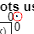

clf
clc
clear

order = 0;
interval = [0, 10];

% Finding roots using each method
tic;
root_fzero = fzeroJ(order, interval);
time_fzero = toc;

tic;
root_bisection = bisectionJ(order, interval);
time_bisection = toc;

tic;
root_newton = newtonJ(order, interval);
time_newton = toc;

tic;
root_secant = secantJ(order, interval);
time_secant = toc;

% Plotting the function and roots
x = linspace(0, 10, 1000);
y = besselj(order, x);
figure;
plot(x, y);
hold on;
plot(root_fzero, besselj(order, root_fzero), 'ro');
title('Approximated Roots using fzero Method');
xlabel('x');
ylabel('besselj(0,x)');
legend('besselj(0,x)', 'Roots');


% Compute average relative error
true_roots = [2.4048255577, 5.5200781103, 8.6537279129]; % Values from Abramowitz and Stegun
approx_roots = [root_fzero, root_bisection, root_newton, root_secant];
avg_rel_error = mean(abs((true_roots - approx_roots) ./ true_roots));

Arrays have incompatible sizes for this operation.

Related documentation


% Output computation time and average relative error
fprintf('Computation time for fzero method: %.4f seconds\n', time_fzero);
fprintf('Computation time for bisection method: %.4f seconds\n', time_bisection);
fprintf('Computation time for Newton method: %.4f seconds\n', time_newton);
fprintf('Computation time for Secant method: %.4f seconds\n', time_secant);
fprintf('Average relative error: %.10f\n', avg_rel_error);


Enter explanation here.

### Your Functions

#### Part 1:

function interp_values = IntPoly(query_points)

    % Number of data points
    n = size(query_points, 1);
    
    % Formulating the Vandermonde matrix
    A = zeros(n);
    for i = 1:n
        for j = 1:n
            A(i, j) = query_points(i, 1)^(j-1);
        end
    end
    
    % Solve for coefficients
    coefficients = A \ query_points(:, 2);
    
    % Evaluate interpolation at query points
    interp_values = polyval(flip(coefficients'), query_points);
end


% M1.2: Lagrange polynomial interpolation
function interp_values = LagrangePoly(query_points)
 
    % Number of data points
    n = size(query_points, 1);
    
    % Initialize interpolated values
    interp_values = zeros(size(query_points));
    
    % Compute Lagrange basis polynomials and interpolate
    for k = 1:n
        basis_poly = ones(size(query_points));
        for j = 1:n
            if j ~= k
                basis_poly = basis_poly .* (query_points - query_points(j, 1)) / (query_points(k, 1) - query_points(j, 1));
            end
        end
        interp_values = interp_values + basis_poly * query_points(k, 2);
    end
end

% M1.3: Cubic spline interpolation with natural end conditions
function interp_values = IntSpline(query_points)
    
    % Number of data points
    n = size(query_points, 1);
    
    % Initialize coefficients
    A = zeros(n-2);
    B = zeros(n-2, 1);
    
    % Construct tridiagonal system
    for i = 1:n-2
        h1 = query_points(i+1, 1) - query_points(i, 1);
        h2 = query_points(i+2, 1) - query_points(i+1, 1);
        A(i, i) = (h1 + h2) / 3;
        if i > 1
            A(i, i-1) = h1 / 6;
        end
        if i < n-2
            A(i, i+1) = h2 / 6;
        end
        B(i) = (query_points(i+2, 2) - query_points(i+1, 2)) / h2 - (query_points(i+1, 2) - query_points(i, 2)) / h1;
    end
    
    % Solve for second derivatives
    M = [0; A \ B; 0];
    
    % Interpolate using cubic spline
    interp_values = zeros(size(query_points));
    for i = 1:n-1
        indices = query_points >= query_points(i, 1) & query_points < query_points(i+1, 1);
        h = query_points(i+1, 1) - query_points(i, 1);
        interp_values(indices) = ((query_points(i+1, 1) - query_points(indices)).^3 * M(i) + ...
            (query_points(indices) - query_points(i, 1)).^3 * M(i+1)) / (6 * h) + ...
            ((query_points(i+1, 2) - query_points(i, 2)) / h - h * (M(i+1) + 2 * M(i)) / 6) * (query_points(indices) - query_points(i, 1)) + ...
            query_points(i, 2);
    end
end

% M1.4: Polynomial interpolation with Chebyshev spacing
function interp_values = IntPolyChebyshev(query_points)
    
    % Number of data points
    n = size(query_points, 1);
    
    % Chebyshev nodes within the range of the data
    cheb_nodes = (query_points(:, 1) - min(query_points(:, 1))) / (max(query_points(:, 1)) - min(query_points(:, 1)));
    cheb_nodes = cos((2 * (1:n)' - 1) * pi / (2 * n));
    
    % Formulating the Vandermonde matrix
    A = zeros(n);
    for i = 1:n
        for j = 1:n
            A(i, j) = cheb_nodes(i)^(j-1);
        end
    end
    
    % Solve for coefficients
    coefficients = A \ query_points(:, 2);
    
    % Evaluate interpolation at query points
    interp_values = polyval(flip(coefficients'), query_points);
end

#### Part 2:

function result = trapzJ1(x, N)
    h = x(1);  % Step size
    f = besselj(1, x);  % Evaluate Bessel function
    result = 0.5 * h * (f(1) + 2*sum(f(2:end-1)) + f(end));  % Trapezium rule
end

function result = simpsonJ1(x, N)
    h = x(1);  % Step size
    f = besselj(1, x);  % Evaluate Bessel function
    result = h/3 * (f(1) + 4*sum(f(2:2:end-1)) + 2*sum(f(3:2:end-2)) + f(end));  % Simpson's 1/3 rule
end

function result = gaussJ1(x, N)
    [xi, wi] = gauss_legendre(N);  % Gauss-Legendre nodes and weights
    f = besselj(1, xi);  % Evaluate Bessel function
    result = sum(wi .* f);  % Gauss-Legendre quadrature
end

function [xi, wi] = gauss_legendre(N)
    % Nodes and weights for Gauss-Legendre quadrature
    % N: Number of points
    beta = 0.5 ./ sqrt(1 - (2*(1:N-1)).^(-2));  % Recurrence coefficients
    [V, D] = eig(diag(beta,1) + diag(beta,-1));  % Eigenvalue decomposition
    [xi, ind] = sort(diag(D));  % Quadrature nodes
    wi = 2 * V(1,ind).^2;  % Quadrature weights
end


#### Part3:

% fzeroJ: Find roots using fzero method
function roots = fzeroJ(order, interval)
    f = @(x) besselj(order, x);
    roots = fzero(f, interval);
end

% bisectionJ: Find roots using bisection method
function roots = bisectionJ(order, interval)
    f = @(x) besselj(order, x);
    roots = roots_bisection(f, interval);
end

% newtonJ: Find roots using Newton's method
function roots = newtonJ(order, interval)
    f = @(x) besselj(order, x);
    df = @(x) (besselj(order-1, x) - besselj(order+1, x)) / 2;
    roots = roots_newton(f, df, interval);
end

% secantJ: Find roots using Secant method
function roots = secantJ(order, interval)
    f = @(x) besselj(order, x);
    roots = roots_secant(f, interval);
end

% Helper function for bisection method
function root = roots_bisection(f, interval)
    a = interval(1);
    b = interval(2);
    tol = 1e-10;
    root = [];
    while abs(b - a) > tol
        c = (a + b) / 2;
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
    end
    root = (a + b) / 2;
end

% Helper function for Newton's method
function root = roots_newton(f, df, interval)
    x0 = (interval(1) + interval(2)) / 2; % Initial guess
    tol = 1e-10;
    root = [];
    while true
        x1 = x0 - f(x0) / df(x0);
        if abs(x1 - x0) < tol
            break;
        end
        x0 = x1;
    end
    root = x1;
end

% Helper function for Secant method
function zeros_f = roots_secant(function_x, range)
    x_1 = range(1);
    x_2 = range(2);
    tolerence = 1e-10;
    zeros_f = [];
    while true
        x_3 = x_2 - function_x(x_2) * ((x_2 - x_1) / (function_x(x_2) - function_x(x_1)));
        if abs(x_3 - x_2) < tolerence
            break;
        end
        x_1 = x_2;
        x_2 = x_3;
    end
    zeros_f = x_3;
end
